## Before Using Verilog

Read the file:

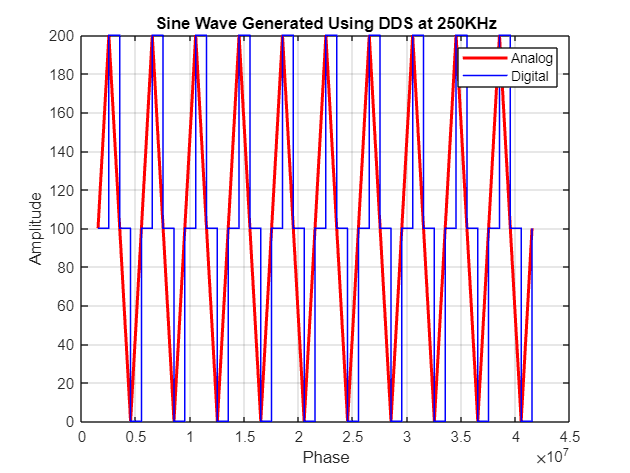

% open the text file
file = fopen('log-250KHz.txt', 'r');

% read the data
data = textscan(file, 'Time: %f, Phase: %d, Data_sin: %d');

% close the file
fclose(file);

% extract the data
time = data{1};
phase = data{2};
data_sin = data{3};

% plot the graphs
figure;
plot(time, data_sin, "r", "LineWidth", 2);
hold on
stairs(time, data_sin, "b", "LineWidth", 1);
hold off

% add relevant labels
legend('Analog', 'Digital');
xlabel('Phase');
ylabel('Amplitude');
title('Sine Wave Generated Using DDS at 250KHz');

grid on;

FFT:

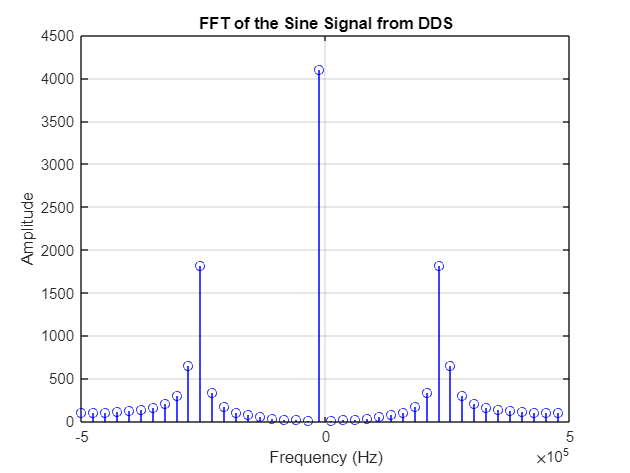

% compute the FFT of the composite signal
fs = 1000000;
fft_signal = fft(data_sin);
N = length(fft_signal);
fft_signal = fftshift(fft_signal);
f_axis = fs*(-N/2:N/2-1)/N;

% Plot the FFT
figure;
stem(f_axis, abs(fft_signal), 'b');
xlabel("Frequency (Hz)"); ylabel("Amplitude");
title("FFT of the Sine Signal from DDS");
grid on;

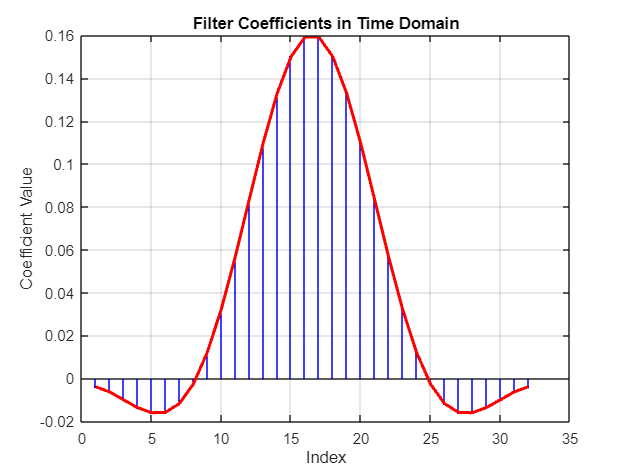

figure;
stem(low_pass_filter, 'b', 'MarkerSize', 1);
hold on
plot(low_pass_filter, 'r', 'LineWidth', 2);
hold off
title('Filter Coefficients in Time Domain');
xlabel('Index');
ylabel('Coefficient Value');
grid on;

% compute the FFT of the composite signal
fft_filter = fft(low_pass_filter);
N = length(fft_filter);
fft_filter = fftshift(fft_filter);
f_axis = fs*(-N/2:N/2-1)/N;

% Plot the FFT
figure;
stem(f_axis, abs(fft_filter), 'b', 'MarkerSize', 1, 'LineWidth', 2);
xlabel("Frequency (Hz)"); ylabel("Amplitude");
title("FFT of the Low Pass Filter");
grid on;

filter_out = filter(low_pass_filter, 1, data_sin);

figure;
plot(time, filter_out, 'r', 'LineWidth', 2);
hold on;
plot(time, data_sin, 'b','LineWidth', 2);
xlabel("Time (us)"); ylabel("Amplitude");
grid on;
legend("Filtered", "Original")

Removing Negative Values from the Coefficients:

Verilog_LPF = [];

for i = 1:32
    if (low_pass_filter(i) >= 0)
        Verilog_LPF(i) = low_pass_filter(i);
    else
        Verilog_LPF(i) = 0;
    end
end

figure;
stem(Verilog_LPF, 'b', 'MarkerSize', 1);
hold on
plot(Verilog_LPF, 'r', 'LineWidth', 2);
hold off
title('Filter Coefficients in Time Domain');
xlabel('Index');
ylabel('Coefficient Value');
grid on;

Scale the values by 255 and then convert into binary.

bits = 8;
new_filter = [];

for i = 1:32
    var = round(Verilog_LPF(i) * 255);
    new_filter{i} = dec2bin(var, bits);
end

disp(new_filter)

## After Verilog

For 250KHz:

% open the text file
file_250 = fopen('Output-Filtered/log-250KHz.txt', 'r');

% read the data
data = textscan(file_250, 'Time: %f, Data_sin: %d, Filtered_Output: %d');

% close the file
fclose(file_250);

% extract the data
time = data{1};
data_sin = data{2};
Data_Out = data{3}./255;

% plot the graphs
figure;
plot(time, data_sin, "r", "LineWidth", 2);
hold on
plot(time, Data_Out, "b", "LineWidth", 1);
hold off

% add relevant labels
legend('Original', 'Filtered');
xlabel('Time');
ylabel('Amplitude');
title('Filtered Output at 250KHz');

grid on;

For 125KHz:

% open the text file
file_125 = fopen('Output-Filtered/log-125KHz.txt', 'r');

% read the data
data = textscan(file_125, 'Time: %f, Data_sin: %d, Filtered_Output: %d');

% close the file
fclose(file_125);

% extract the data
time = data{1};
data_sin = data{2};
Data_Out = data{3}./255;

% plot the graphs
figure;
plot(time, data_sin, "r", "LineWidth", 2);
hold on
plot(time, Data_Out, "b", "LineWidth", 1);
hold off

% add relevant labels
legend('Original', 'Filtered');
xlabel('Time');
ylabel('Amplitude');
title('Filtered Output at 125KHz');

grid on;

For 40KHz:

% open the text file
file_40 = fopen('Output-Filtered/log-40KHz.txt', 'r');

% read the data
data = textscan(file_40, 'Time: %f, Data_sin: %d, Filtered_Output: %d');

% close the file
fclose(file_40);

% extract the data
time = data{1};
data_sin = data{2};
Data_Out = data{3}./255;

% plot the graphs
figure;
plot(time, data_sin, "r", "LineWidth", 2);
hold on
plot(time, Data_Out, "b", "LineWidth", 1);
hold off

% add relevant labels
legend('Original', 'Filtered');
xlabel('Time');
ylabel('Amplitude');
title('Filtered Output at 40KHz');

grid on;

For 10KHz:

% open the text file
file_10 = fopen('Output-Filtered/log-10KHz.txt', 'r');

% read the data
data = textscan(file_10, 'Time: %f, Data_sin: %d, Filtered_Output: %d');

% close the file
fclose(file_10);

% extract the data
time = data{1};
data_sin = data{2};
Data_Out = data{3}./255;

% plot the graphs
figure;
plot(time, data_sin, "r", "LineWidth", 2);
hold on
plot(time, Data_Out, "b", "LineWidth", 1);
hold off

% add relevant labels
legend('Original', 'Filtered');
xlabel('Time');
ylabel('Amplitude');
title('Filtered Output at 10KHz');

grid on;